# Aligning Sequences

by AhmetSacan

## Obtaining the sequences

Search the web for AGRE1_RAT Adhesion G protein-coupled receptor E2 protein. Download the protein sequence.

ratptnfile = bmes.downloadurl('https://www.uniprot.org/uniprot/Q5Y4N8.fasta','rat.agre1.ptn.fasta')

ratptnfile = 'C:/Users/ahmet/AppData/Local/Temp/bmes/rat.agre1.ptn.fasta'


% also find and download the human protein, AGRE1_HUMAN
humptnfile = bmes.downloadurl('https://www.uniprot.org/uniprot/Q14246.fasta')

humptnfile = 'C:/Users/ahmet/AppData/Local/Temp/bmes/Q14246uniprotwww.uniprot.org.fasta'

## Reading fasta file

ratptn = fastaread(ratptnfile)

ratptn = struct with fields:
      Header: 'sp|Q5Y4N8|AGRE1_RAT Adhesion G protein-coupled receptor E2 OS=Rattus norvegicus OX=10116 GN=Adgre1 PE=2 SV=1'
    Sequence: 'MWGFWLLLFWGFSGTHRWGMTTLAILGQRLNGVNECQDTTTCPAYATCTDTTESYYCTCKQGFLPSNGQTNFQGPGVECQDVNECLRSDSPCGSNSVCTNIPGRARCSCLSGFSSSAGGSWILGSPGHFLCTDVDECLTIGICPKNSNCSNSVGSYSCTCQSGFVSNGSTCEDEDECVTRNACPEHATCHNTLGSYYCTCNEGLEFSGGGPMFQGLEESCEDVDECSRNSTLCGPSFICINTLGSYSCSCPAGFSLSTFQIPGHPADGNCTDIDECDDICPSNSSCTNTLGSYFCTCHPGFASSNGQLNFTDQEVTCEDIDECTQDPFRCGRNSSCTNVPGSYNCSCLPDFRMDPGGSQAHGNFTCKRIPFKCKEDLIPKSEQIEQCQAGQGRNLDYTSFCTFVNATFTILDNTCENKSAPVSLQSAATSVSLMLEQASTWFEFSREETSTLGTILLETVESTMLAALLTPSGNASQTIRTEYLEIESKVINEECNEENVSINLKARGDKMDVGCFIIKESESTGTPGVAFVSFAHMDSVLDERFFEDGQASWKLRMNSHVVGGTVTGERKEDFSKPIVYTLQHIQPKQKSERSICVSWNTDVEDGRWTPSGCETVEASETHTVCSCNRMTNLAIIMASGELTMEFSLYIISYVGTVISLVCLALAIATFLLFRAVQNHNTYLHLHLCVCLFLAKILFLTGIDKTDNQTACAIIAGFLHYLFLACFFWMLVEAVMLFLMVRNLKVVNYFSSRNIKMLHLCAFGYGLPVVVVIISATVHPWGYGMHNRCWLNTETGFIWSFLGPVCMIITINSALLAWTLWVLRQKLCSVNS

## Self-dot-plot

use window size=10, match filter 5 to filter out noise.

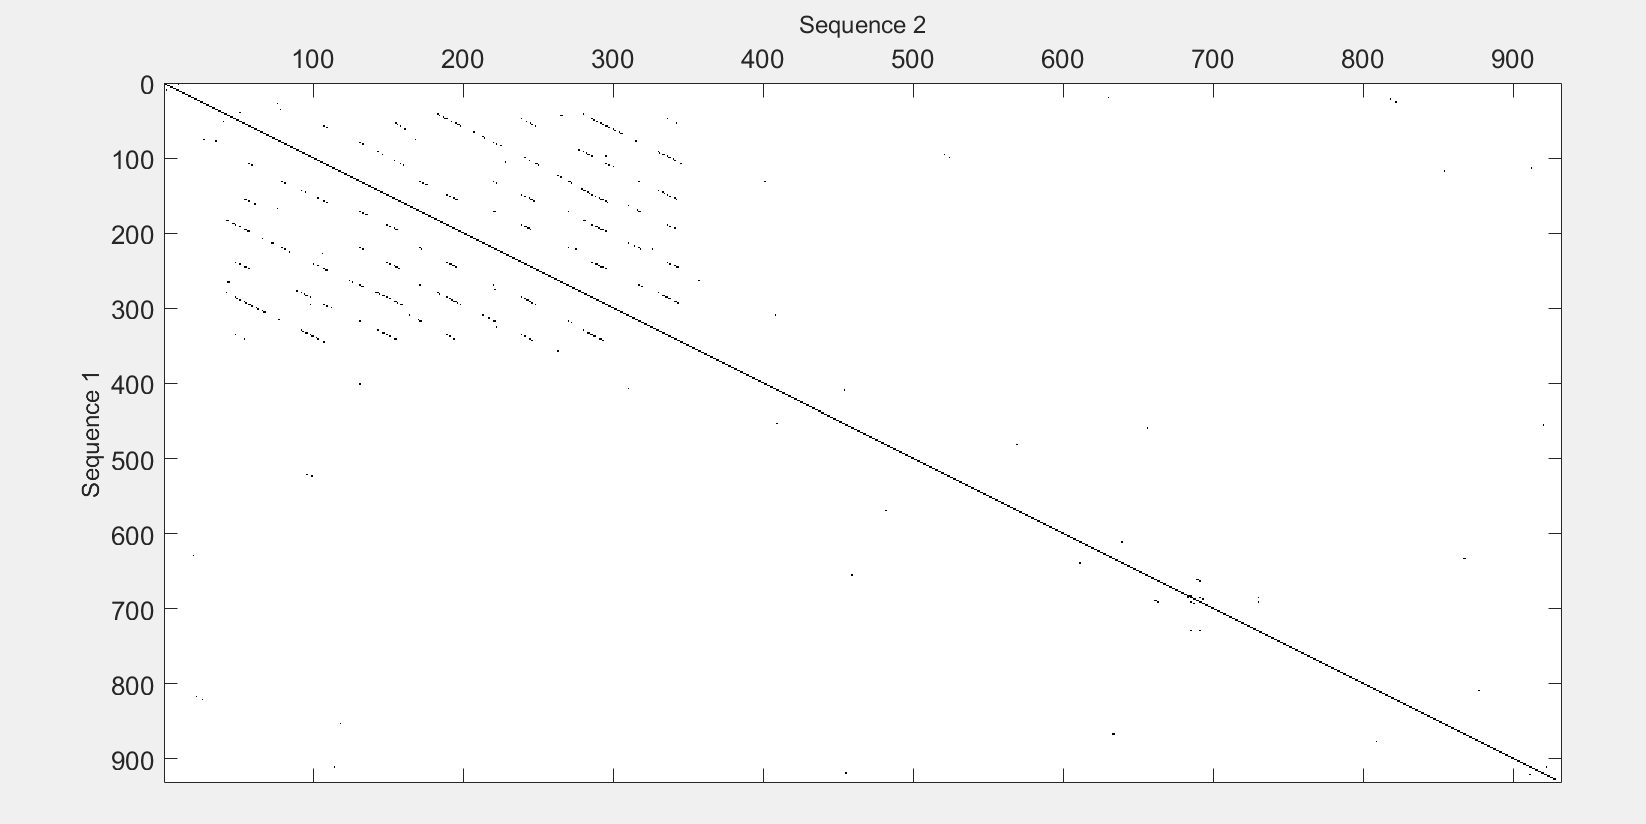

seqdotplot(ratptn, ratptn, 10, 5)

## Sequence alignments

ratptn = fastaread(ratptnfile);
humptn = fastaread(humptnfile);

## Local alignment

[score, align] = swalign(ratptn,humptn,'alphabet','aa')

score = 1.2933e+03

align = 3×938 char array
    'MWGFWLLLFWGFSGTHRW-GMTTLAILGQRLNGVNECQDTTTCPAYATCTDTTESYYCTCKQGFLPSNGQTNFQGPGVECQDVNECLRSDSPCGSNSVCTNIPGRARCSCLSGFSSSAGGSWILGSPGHFLCTDVDECLTIGICPKNSNCSNSVGSYSCTCQSGFVSNGSTCEDEDECVTRNACPEHATCHNTLGSYYCTCNEGLEFSGGGPMFQGLEESCEDVDECSRNSTLCGPSFICINTLGSYSCSCPAGFSLSTFQIPGHPADGNCTDIDECDDICPSNSSCTNTLGSYFCTCHPGFASSNGQLNFTDQEVTCEDIDECTQDPFRCGRNSSCTNVPGSYNCSCLPDFRMDPGGSQAHGNFTCKRIPFKCKEDLIPKSEQIEQCQAGQGRNLDYTSFCTFVNATFTILDNTCENKSAPVSLQSAATSVSLMLEQASTWFEFSREETSTLGTILLETVESTMLAALLTPSGNASQTIRTEYLEIESKVINEECNEENVSINLKARGDKMDVGCFIIKESESTGTPGVAFVSFAHMDSVLDERFFEDGQA----S-WKLRMNSHVVGGTVTGERKEDFSKPIVYTLQHIQPKQKSERSICVSWNTDVEDGRWTPSGCETVEASETHTVCSCNRMTNLAIIMASGELTMEFSLYIISYVGTVISLVCLALAIATFLLFRAVQNHNTYLHLHLCVCLFLAKILFLTGIDKTDNQTACAIIAGFLHYLFLACFFWMLVEAVMLFLMVRNLKVVNYFSSRNIKMLHLCAFGYGLPVVVVIISATVHPWGYGMHNRCWLNTETGFIWSFLGPVCMIITINSALLAWTLWVLRQKLCSVNSEVSKLKDTRLLTFKAIAQIFILGCSWVLGIFQIGPLASIMAYLFTTINSLQGAFIFLIHCLLNRQVRDEYRKLLTRKTDLSSHSQTSGILLSSMPSTSKTG'
    '| || ||||||    | | |     

## Global alignment

[score, align] = nwalign(ratptn,humptn,'alphabet','aa')

score = 1.2933e+03

align = 3×938 char array
    'MWGFWLLLFWGFSGTHRW-GMTTLAILGQRLNGVNECQDTTTCPAYATCTDTTESYYCTCKQGFLPSNGQTNFQGPGVECQDVNECLRSDSPCGSNSVCTNIPGRARCSCLSGFSSSAGGSWILGSPGHFLCTDVDECLTIGICPKNSNCSNSVGSYSCTCQSGFVSNGSTCEDEDECVTRNACPEHATCHNTLGSYYCTCNEGLEFSGGGPMFQGLEESCEDVDECSRNSTLCGPSFICINTLGSYSCSCPAGFSLSTFQIPGHPADGNCTDIDECDDICPSNSSCTNTLGSYFCTCHPGFASSNGQLNFTDQEVTCEDIDECTQDPFRCGRNSSCTNVPGSYNCSCLPDFRMDPGGSQAHGNFTCKRIPFKCKEDLIPKSEQIEQCQAGQGRNLDYTSFCTFVNATFTILDNTCENKSAPVSLQSAATSVSLMLEQASTWFEFSREETSTLGTILLETVESTMLAALLTPSGNASQTIRTEYLEIESKVINEECNEENVSINLKARGDKMDVGCFIIKESESTGTPGVAFVSFAHMDSVLDERFFEDGQA----S-WKLRMNSHVVGGTVTGERKEDFSKPIVYTLQHIQPKQKSERSICVSWNTDVEDGRWTPSGCETVEASETHTVCSCNRMTNLAIIMASGELTMEFSLYIISYVGTVISLVCLALAIATFLLFRAVQNHNTYLHLHLCVCLFLAKILFLTGIDKTDNQTACAIIAGFLHYLFLACFFWMLVEAVMLFLMVRNLKVVNYFSSRNIKMLHLCAFGYGLPVVVVIISATVHPWGYGMHNRCWLNTETGFIWSFLGPVCMIITINSALLAWTLWVLRQKLCSVNSEVSKLKDTRLLTFKAIAQIFILGCSWVLGIFQIGPLASIMAYLFTTINSLQGAFIFLIHCLLNRQVRDEYRKLLTRKTDLSSHSQTSGILLSSMPSTSKTG'
    '| || ||||||    | | |     

custom gap penalties

[score, align] = nwalign(ratptn,humptn,'alphabet','aa','gapopen',10,'extendgap',1)

score = 1.4027e+03

align = 3×937 char array
    'MWGFWLLLFWGFSGTHRWGMTTLAILGQRLNGVNECQDTTTCPAYATCTDTTESYYCTCKQGFLPSNGQTNFQGPGVECQDVNECLRSDSPCGSNSVCTNIPGRARCSCLSGFSSSAGGSWILGSPGHFLCTDVDECLTIGICPKNSNCSNSVGSYSCTCQSGFVSNGSTCEDEDECVTRNACPEHATCHNTLGSYYCTCNEGLEFSGGGPMFQGLEESCEDVDECSRNSTLCGPSFICINTLGSYSCSCPAGFSLSTFQIPGHPADGNCTDIDECDDICPSNSSCTNTLGSYFCTCHPGFASSNGQLNFTDQEVTCEDIDECTQDPFRCGRNSSCTNVPGSYNCSCLPDFRMDPGGSQAHGNFTCKRIPFKCKEDLIPKSEQIEQCQAGQGRNLDYTSFCTFVNATFTILDNTCENKSAPVSLQSAATSVSLMLEQASTWFEFSREETSTLGTILLETVESTMLAALLTPSGNASQTIRTEYLEIESKVINEECNEENVSINLKARGDKMDVGCFIIKESESTGTPGVAFVSFAHMDSVLDERFFEDGQASW-----KLRMNSHVVGGTVTGERKEDFSKPIVYTLQHIQPKQKSERSICVSWNTDVEDGRWTPSGCETVEASETHTVCSCNRMTNLAIIMASGELTMEFSLYIISYVGTVISLVCLALAIATFLLFRAVQNHNTYLHLHLCVCLFLAKILFLTGIDKTDNQTACAIIAGFLHYLFLACFFWMLVEAVMLFLMVRNLKVVNYFSSRNIKMLHLCAFGYGLPVVVVIISATVHPWGYGMHNRCWLNTETGFIWSFLGPVCMIITINSALLAWTLWVLRQKLCSVNSEVSKLKDTRLLTFKAIAQIFILGCSWVLGIFQIGPLASIMAYLFTTINSLQGAFIFLIHCLLNRQVRDEYRKLLTRKTDLSSHSQTSGILLSSMPSTSKTG'
    '| || ||||||    | |        

custom scoring matrix Get the blosum62 matrix so we have the right size, then modify it to our liking.

M = blosum62

M =      4    -1    -2    -2     0    -1    -1     0    -2    -1    -1    -1    -1    -2    -1     1     0    -3    -2     0    -2    -1     0    -4
    -1     5     0    -2    -3     1     0    -2     0    -3    -2     2    -1    -3    -2    -1    -1    -3    -2    -3    -1     0    -1    -4
    -2     0     6     1    -3     0     0     0     1    -3    -3     0    -2    -3    -2     1     0    -4    -2    -3     3     0    -1    -4
    -2    -2     1     6    -3     0     2    -1    -1    -3    -4    -1    -3    -3    -1     0    -1    -4    -3    -3     4     1    -1    -4
     0    -3    -3    -3     9    -3    -4    -3    -3    -1    -1    -3    -1    -2    -3    -1    -1    -2    -2    -1    -3    -3    -2    -4
    -1     1     0     0    -3     5     2    -2     0    -3    -2     1     0    -3    -1     0    -1    -2    -1    -2     0     3    -1    -4
    -1     0     0     2    -4     2     5    -2     0    -3    -3     1    -2    -3    -1     0    -1    -3    -2    -2     1

M = eye(size(M))*2-1

M =      1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1

[score, align] = nwalign(ratptn,humptn,'alphabet','aa','scoringmatrix',M)

score = -123

align = 3×937 char array
    'MWGFWLLLFWGFSGTHRWGMTTLAILGQRLNGVNECQDTTTCPAYATCTDTTESYYCTCKQGFLPSNGQTNFQGPGVECQDVNECLRSDSPCGSNSVCTNIPGRARCSCLSGFSSSAGGSWILGSPGHFLCTDVDECLTIGICPKNSNCSNSVGSYSCTCQSGFVSNGSTCEDEDECVTRNACPEHATCHNTLGSYYCTCNEGLEFSGGGPMFQGLEESCEDVDECSRNSTLCGPSFICINTLGSYSCSCPAGFSLSTFQIPGHPADGNCTDIDECDDICPSNSSCTNTLGSYFCTCHPGFASSNGQLNFTDQEVTCEDIDECTQDPFRCGRNSSCTNVPGSYNCSCLPDFRMDPGGSQAHGNFTCKRIPFKCKEDLIPKSEQIEQCQAGQGRNLDYTSFCTFVNATFTILDNTCENKSAPVSLQSAATSVSLMLEQASTWFEFSREETSTLGTILLETVESTMLAALLTPSGNASQTIRTEYLEIESKVINEECNEENVSINLKARGDKMDVGCFIIKESESTGTPGVAFVSFAHMDSVLDERFFEDGQA----S-WKLRMNSHVVGGTVTGERKEDFSKPIVYTLQHIQPKQKSERSICVSWNTDVEDGRWTPSGCETVEASETHTVCSCNRMTNLAIIMASGELTMEFSLYIISYVGTVISLVCLALAIATFLLFRAVQNHNTYLHLHLCVCLFLAKILFLTGIDKTDNQTACAIIAGFLHYLFLACFFWMLVEAVMLFLMVRNLKVVNYFSSRNIKMLHLCAFGYGLPVVVVIISATVHPWGYGMHNRCWLNTETGFIWSFLGPVCMIITINSALLAWTLWVLRQKLCSVNSEVSKLKDTRLLTFKAIAQIFILGCSWVLGIFQIGPLASIMAYLFTTINSLQGAFIFLIHCLLNRQVRDEYRKLLTRKTDLSSHSQTSGILLSSMPSTSKTG'
    '| || ||||||    | |        